%% CLIMATE RISK & GROWTH CHART (Corrected, Robust, Descriptive, Dark Theme)
% Script prepared for Cantine Riunite - Denmark strategic analysis
% Comments in English

% 1. Load data and inspect column names
data = readtable('wine_data.csv');
disp('Table variable names:');

Table variable names:


disp(data.Properties.VariableNames);

    {'Year'}    {'Revenue_MEuro'}    {'SalesVolume_kHL'}    {'ClimateRiskIndex'}    {'TempAnomaly_C'}    {'ExtremeWeatherFreq'}



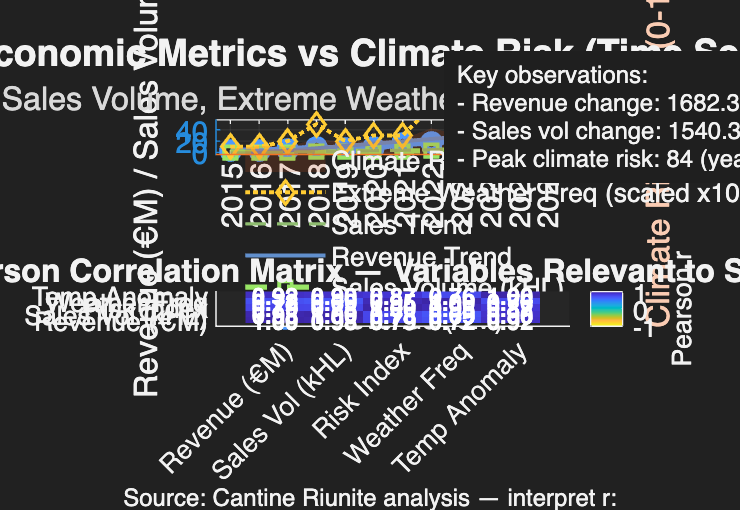


% 2. Map expected variable names to actual names in the table (case-insensitive heuristics)
expectedMap = { ...
    'Revenue_MEuro',   {'revenue','rev','revenue_meuro','revenue (meuro)'}; ...
    'SalesVolume_kHL', {'sales','volume','salesvolume','sales_khl','sales volume'}; ...
    'ClimateRiskIndex',{'risk','climate','climaterisk','climate_risk_index'}; ...
    'TempAnomaly',     {'temp','anomaly','temperature','temp_anomaly','temperatureanomaly'}; ...
    'ExtremeWeatherFreq', {'extreme','weather','extremeweather','extreme_weather_freq','weatherfreq'} ...
    };

actualNames = cell(size(expectedMap,1),1);
varsAvailable = lower(data.Properties.VariableNames);
for k = 1:size(expectedMap,1)
    expectedLabel = expectedMap{k,1};
    candidates = expectedMap{k,2};
    found = '';
    % try exact match first (case-insensitive)
    idx = find(strcmpi(data.Properties.VariableNames, expectedLabel), 1);
    if ~isempty(idx)
        found = data.Properties.VariableNames{idx};
    else
        % search by candidate substrings
        for c = 1:numel(candidates)
            matchIdx = find(contains(varsAvailable, lower(candidates{c})), 1);
            if ~isempty(matchIdx)
                found = data.Properties.VariableNames{matchIdx};
                break;
            end
        end
    end
    if isempty(found)
        warning('Could not find a column for "%s". Please check CSV column names.', expectedLabel);
        actualNames{k} = '';
    else
        actualNames{k} = found;
    end
end

% 3. Validate and assign fallbacks or error out if essential columns missing
% Essential: Year, Revenue and Sales (adjust as needed)
if ~ismember('Year', data.Properties.VariableNames)
    error('CSV must contain a ''Year'' column.');
end
yearCol = 'Year';

% Build a map from expected label to actual column name or raise clear error
mapStruct = struct();
for k = 1:size(expectedMap,1)
    key = expectedMap{k,1};
    val = actualNames{k};
    if isempty(val)
        % Allow TempAnomaly missing (not strictly fatal) but warn; others are required
        if strcmp(key, 'TempAnomaly')
            fprintf('Note: Temperature anomaly column not found. It will be omitted from correlation matrix.\n');
            mapStruct.(key) = '';
        else
            error('Required column for "%s" not found. Available columns: %s', key, strjoin(data.Properties.VariableNames, ', '));
        end
    else
        mapStruct.(key) = val;
    end
end

% 4. Extract variables safely (handle missing TempAnomaly)
years = data.(yearCol);
Revenue = data.(mapStruct.Revenue_MEuro);
SalesVol = data.(mapStruct.SalesVolume_kHL);
RiskIdx = data.(mapStruct.ClimateRiskIndex);
ExtremeFreq = data.(mapStruct.ExtremeWeatherFreq);
if ~isempty(mapStruct.TempAnomaly)
    TempAnom = data.(mapStruct.TempAnomaly);
else
    TempAnom = [];
end

% 5. Create figure and apply dark theme (use theme() if available)
fig = figure('Position', [100, 100, 1100, 760]);
if exist('theme','file') == 2
    try
        theme(fig, "dark");
    catch
        fig.Color = [0.12, 0.12, 0.12];
    end
else
    fig.Color = [0.12, 0.12, 0.12];
end

% Palette and common colors
palette = [0.3 0.6 1.0;  % revenue
           0.6 0.9 0.4;  % sales
           1.0 0.8 0.2]; % extreme weather
bgAxes = [0.15 0.15 0.15];
textCol = [0.95 0.95 0.95];
gridCol = [0.35 0.35 0.35];

tl = tiledlayout(2,1, 'TileSpacing','compact','Padding','loose');

% --- TOP: Time Series with dual axis, trends, percent changes and annotations
ax1 = nexttile;
hold(ax1, 'on');
ax1.Color = bgAxes;
ax1.FontSize = 11;
ax1.XColor = textCol;
ax1.YColor = textCol;

% Left axis: Revenue and Sales
yyaxis(ax1, 'left');
pRev = plot(years, Revenue, '-o', 'LineWidth', 2.5, 'MarkerSize',6, 'Color', palette(1,:));
pRev.DisplayName = 'Revenue (€M)';
pRev.SeriesIndex = 1;

pSales = plot(years, SalesVol, '--s', 'LineWidth', 2, 'MarkerSize',6, 'Color', palette(2,:));
pSales.DisplayName = 'Sales Volume (kHL)';
pSales.SeriesIndex = 2;

ylabel(ax1, 'Revenue (€M) / Sales Volume (kHL)', 'Color', textCol);

% Left axis autoscale with margin
leftMin = min([Revenue; SalesVol]);
leftMax = max([Revenue; SalesVol]);
if isnan(leftMin) || isnan(leftMax) || leftMin==leftMax
    yyaxis(ax1,'left'); ylim([0, max([Revenue; SalesVol])*1.1]);
else
    pad = 0.08*(leftMax-leftMin);
    yyaxis(ax1,'left'); ylim([leftMin - pad, leftMax + pad]);
end

% Trends: linear fits
try
    cRev = polyfit(years, Revenue, 1);
    trendRev = polyval(cRev, years);
    plot(years, trendRev, '-', 'Color', palette(1,:)*0.6 + 0.2, 'LineWidth', 1.5, 'DisplayName', 'Revenue Trend');
end
try
    cSales = polyfit(years, SalesVol, 1);
    trendSales = polyval(cSales, years);
    plot(years, trendSales, '--', 'Color', palette(2,:)*0.6 + 0.2, 'LineWidth', 1.2, 'DisplayName', 'Sales Trend');
end

% Percent change annotations
if numel(Revenue) >= 2 && Revenue(1) ~= 0
    revPct = (Revenue(end) - Revenue(1)) / abs(Revenue(1)) * 100;
else
    revPct = NaN;
end
if numel(SalesVol) >= 2 && SalesVol(1) ~= 0
    volPct = (SalesVol(end) - SalesVol(1)) / abs(SalesVol(1)) * 100;
else
    volPct = NaN;
end
if ~isnan(revPct)
    text(years(end)+0.25, Revenue(end), sprintf('%.1f%%', revPct), 'Color', palette(1,:), 'FontWeight', 'bold');
end
if ~isnan(volPct)
    text(years(end)+0.25, SalesVol(end), sprintf('%.1f%%', volPct), 'Color', palette(2,:), 'FontWeight', 'bold');
end

% Right axis: Climate Risk (shaded area)
yyaxis(ax1, 'right');
hArea = area(years, RiskIdx, 'FaceColor', [0.85 0.33 0.1], 'FaceAlpha', 0.18, 'EdgeColor', 'none');
hArea.DisplayName = 'Climate Risk Index (0-100)';
ylabel(ax1, 'Climate Risk Index (0-100)', 'Color', [0.98 0.8 0.7]);
yyaxis(ax1,'right'); ylim([0, max(105, max(RiskIdx)*1.05)]);

% Plot Extreme Weather on left axis scaled for visibility
yyaxis(ax1,'left');
pExtreme = plot(years, ExtremeFreq * 10, ':d', 'LineWidth', 1.5, 'MarkerSize',6, 'Color', palette(3,:));
pExtreme.DisplayName = 'Extreme Weather Freq (scaled x10)';
pExtreme.SeriesIndex = 3;

% Axes and styling
ax1.Box = 'on';
grid(ax1, 'on');
ax1.GridColor = gridCol;
ax1.XLim = [min(years)-0.5, max(years)+0.8];
ax1.XTick = unique(years);
ax1.Title.Color = textCol;

title(ax1, 'Economic Metrics vs Climate Risk (Time Series)', 'Color', textCol, 'FontSize', 14);
subtitle(ax1, 'Revenue, Sales Volume, Extreme Weather (scaled) and Climate Risk Index', 'Color', [0.85 0.85 0.85]);

lg = legend(ax1, 'Location', 'northwest', 'TextColor', textCol);
lg.Box = 'off';

% Observations textbox
peakRisk = max(RiskIdx);
peakRiskYear = years(find(RiskIdx == peakRisk, 1, 'first'));
obs = { 'Key observations:', ...
        sprintf('- Revenue change: %s', ternary(~isnan(revPct), sprintf('%.1f%% (%.1f → %.1f)', revPct, Revenue(1), Revenue(end)), 'N/A')), ...
        sprintf('- Sales vol change: %s', ternary(~isnan(volPct), sprintf('%.1f%% (%.1f → %.1f)', volPct, SalesVol(1), SalesVol(end)), 'N/A')), ...
        sprintf('- Peak climate risk: %.0f (year %d)', peakRisk, peakRiskYear) };
annotation('textbox', [0.60, 0.72, 0.33, 0.18], 'String', obs, 'FitBoxToText','on', ...
           'BackgroundColor', [0.12 0.12 0.12 0.6], 'EdgeColor', 'none', 'Color', textCol, 'FontSize', 9);

% --- BOTTOM: Correlation matrix (robust, includes TempAnom if present)
ax2 = nexttile;
ax2.Color = bgAxes;
hold(ax2, 'on');

% Prepare variables and labels depending on availability of TempAnom
corrVars = [Revenue, SalesVol, RiskIdx, ExtremeFreq];
corrNames = {'Revenue (€M)', 'Sales Vol (kHL)', 'Risk Index', 'Weather Freq'};
if ~isempty(TempAnom)
    corrVars = [corrVars, TempAnom];
    corrNames = [corrNames, 'Temp Anomaly'];
end

% Compute Pearson correlation with pairwise deletion of NaNs
corrMat = corr(corrVars, 'Rows', 'pairwise');

% Use a diverging colormap centered at 0: make custom coolwarm using built-ins
nmap = 256;
c1 = flipud( (parula(nmap)) ); % fallback that contrasts on dark bg
colormap(ax2, c1);
imagesc(ax2, corrMat, [-1 1]);
cb = colorbar(ax2, 'eastoutside');
cb.Label.String = 'Pearson r';
cb.Color = textCol;
cb.FontSize = 10;

% Numeric labels inside cells
[rowsN, colsN] = size(corrMat);
for i = 1:rowsN
    for j = 1:colsN
        v = corrMat(i,j);
        % Choose white or near-white for text to ensure contrast on dark figure
        txtColor = [1 1 1] * (abs(v) > 0.5) + [0.95 0.95 0.95]*0.85 * (abs(v) <= 0.5);
        text(ax2, j, i, sprintf('%.2f', v), 'HorizontalAlignment', 'center', 'Color', txtColor, 'FontWeight', 'bold', 'FontSize', 9);
    end
end

% Axis labels and formatting
set(ax2, 'XTick', 1:colsN, 'XTickLabel', corrNames, 'YTick', 1:rowsN, 'YTickLabel', corrNames, ...
    'XTickLabelRotation', 45, 'TickLength', [0 0], 'XColor', textCol, 'YColor', textCol, 'FontSize', 10);
title(ax2, 'Pearson Correlation Matrix — Variables Relevant to Strategy', 'Color', textCol, 'FontSize', 12);

% Footer annotation
annotation('textbox', [0.12, 0.02, 0.76, 0.05], 'String', ...
    'Source: Cantine Riunite analysis — interpret r: |r|>0.5 strong, 0.3-0.5 moderate, <0.3 weak.', ...
    'EdgeColor','none', 'HorizontalAlignment','center', 'Color', textCol, 'FontSize',9);


drawnow;

% --- Helper nested function: compact ternary for text building ---
function out = ternary(cond, a, b)
    if cond
        out = a;
    else
        out = b;
    end
end
